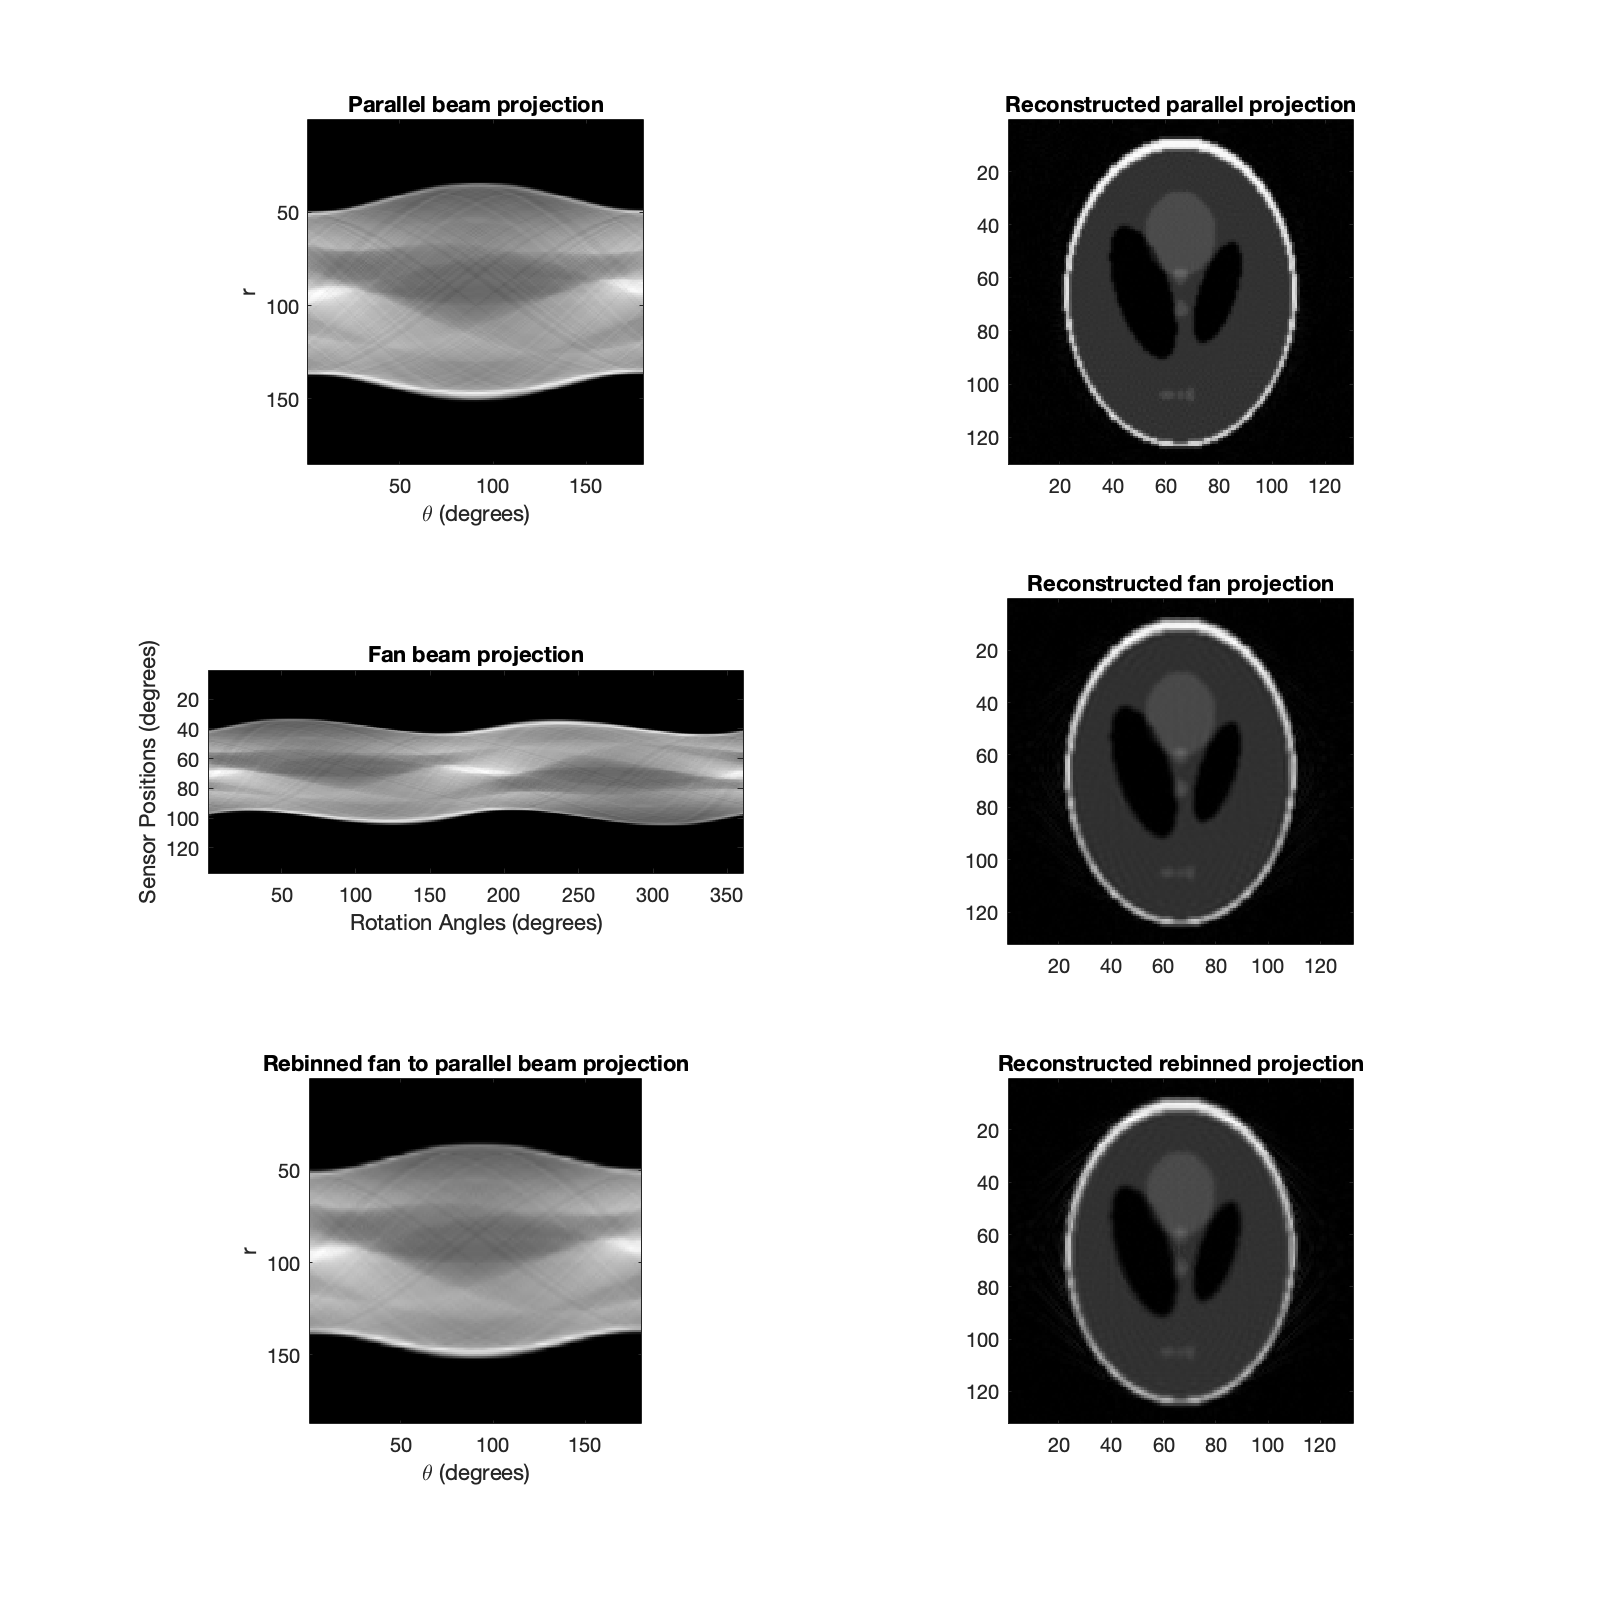

ph = phantom(128);
theta = 0:179;

% Parallel beam projection
[Psynthetic,xp] = radon(ph,theta);

% Fan beam projection
d = 100; % the distance from the fan-beam vertex to the center of rotation.
Fsynthetic = para2fan(Psynthetic,d,'FanSensorSpacing',1);

% Rebinned fan to parallel beam projection
[Precovered,Ploc,Pangles] = fan2para(Fsynthetic,d,...
                                      'FanSensorSpacing',1,...
                                      'ParallelSensorSpacing',1);
% Reconstructed rebinned projection
recon_par = iradon(Psynthetic,theta);
recon_fan = ifanbeam(Fsynthetic,d);
recon_rebin = iradon(Precovered,theta);

figure('Position', [100, 100, 800, 800]); % [left, bottom, width, height]
subplot(3,2,1); imagesc(Psynthetic); axis equal tight; colormap gray;
title('Parallel beam projection')
xlabel('\theta (degrees)')
ylabel('r')
subplot(3,2,2); imagesc(abs(recon_par)); axis equal tight; colormap gray;
title('Reconstructed parallel projection')
subplot(3,2,3); imagesc(abs(Fsynthetic)); axis equal tight; colormap gray;
title('Fan beam projection')
xlabel('Rotation Angles (degrees)')
ylabel('Sensor Positions (degrees)')
subplot(3,2,4); imagesc(abs(recon_fan)); axis equal tight; colormap gray;
title('Reconstructed fan projection');
subplot(3,2,5); imagesc(abs(Precovered)); axis equal tight; colormap gray;
title('Rebinned fan to parallel beam projection')
xlabel('\theta (degrees)')
ylabel('r')
subplot(3,2,6); imagesc(abs(recon_rebin)); axis equal tight; colormap gray;
title('Reconstructed rebinned projection');

err = immse(Precovered(1:185,:), Psynthetic);
fprintf('Mean square error between original parallel beam and rebinned fan beam sinogram: %.3f\n', err);

Mean square error between original parallel beam and rebinned fan beam sinogram: 2.612


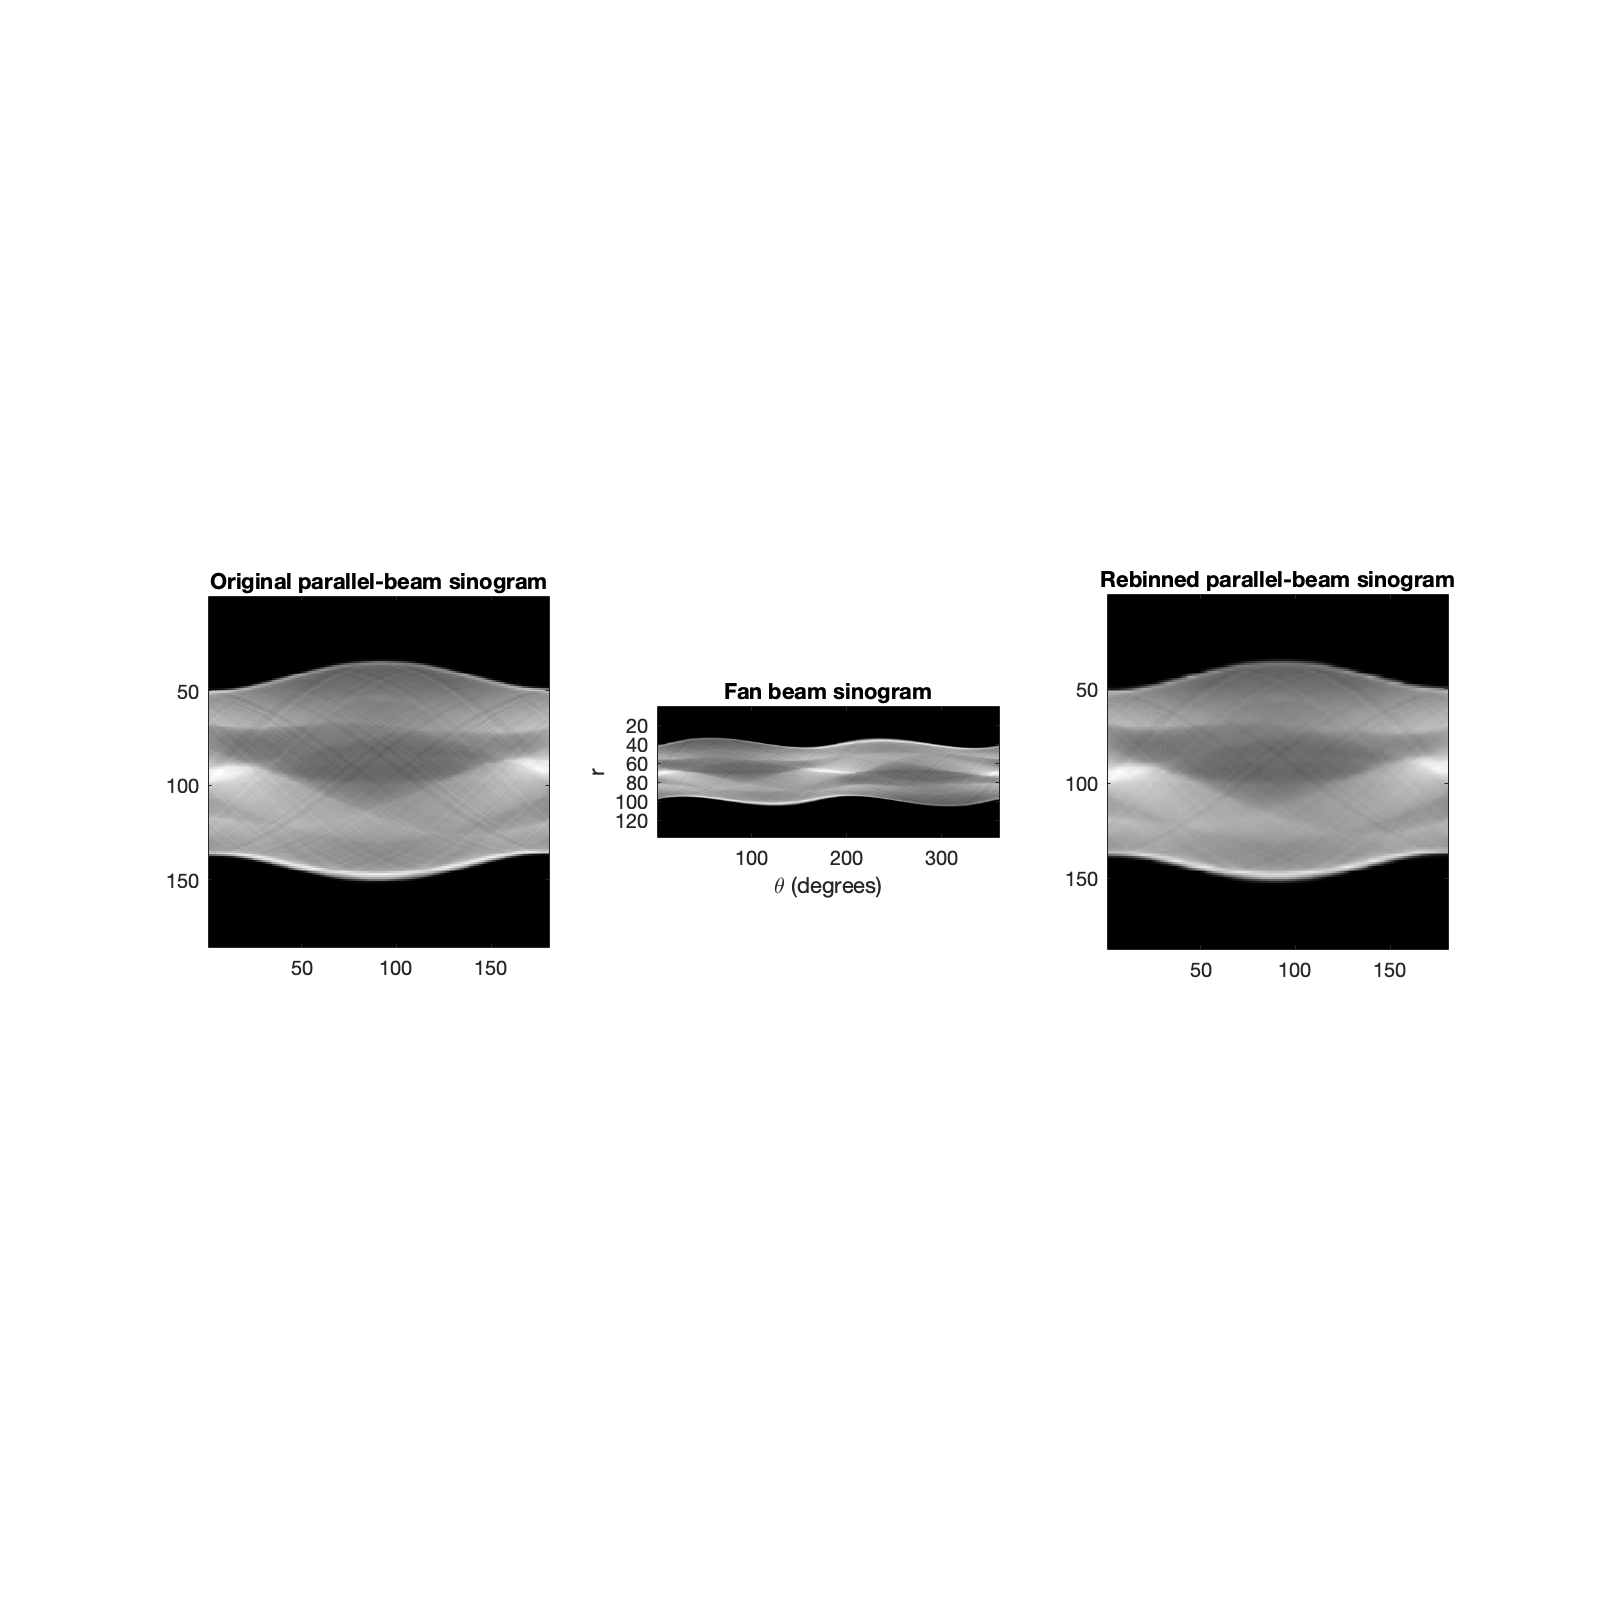

figure('Position', [100, 100, 800, 800]); % [left, bottom, width, height]
subplot(1,3,1); imagesc(abs(Psynthetic)); axis equal tight; colormap gray;
title('Original parallel-beam sinogram')
subplot(1,3,2); imagesc(abs(Fsynthetic)); axis equal tight; colormap gray;
title('Fan beam sinogram')
xlabel('\theta (degrees)')
ylabel('r')
subplot(1,3,3); imagesc(abs(Precovered)); axis equal tight; colormap gray;
title('Rebinned parallel-beam sinogram')